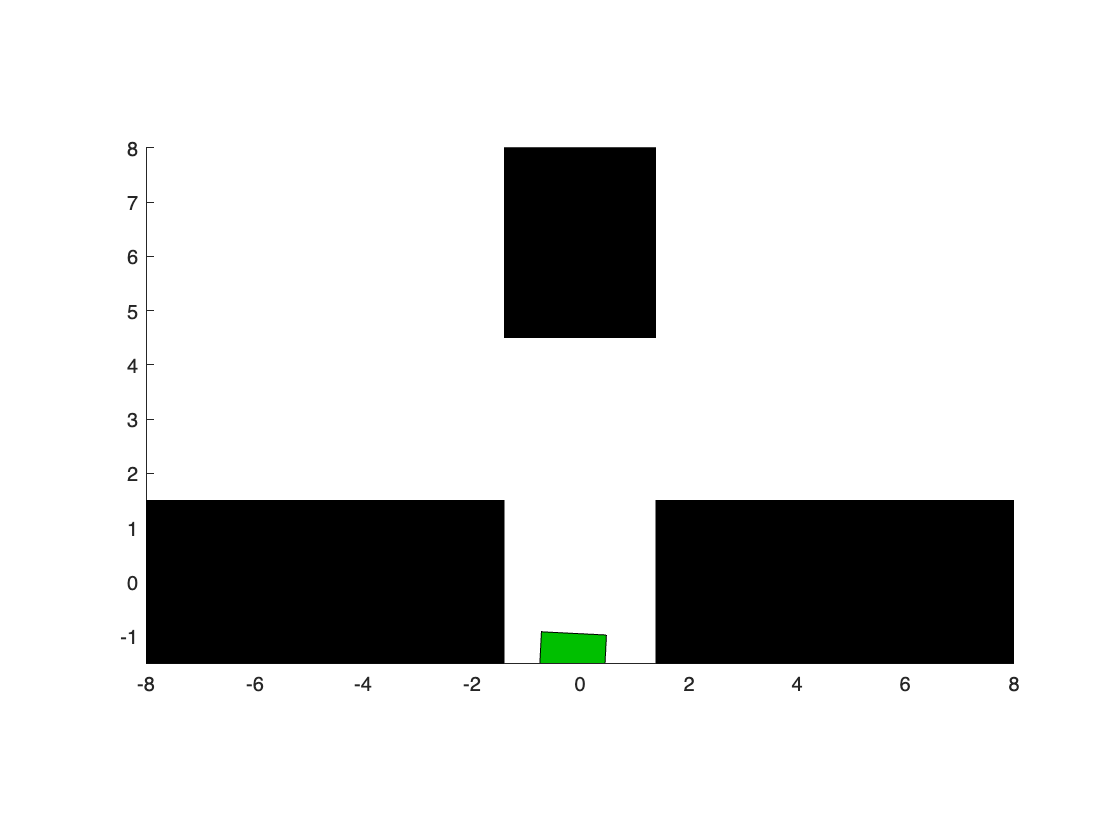

obsDim = [6,1];
obsInfo = rlNumericSpec(obsDim);
actDim = [2,1];
actInfo = rlNumericSpec(actDim, "LowerLimit", -1, "UpperLimit", 1);

env = rlSimulinkEnv("whrobot", "whrobot/controller", obsInfo, actInfo);

env.ResetFcn = @randomstart;


%simulating in the enviroment we just created
rng(423);
load robotmodel agent;
%sim(agent,env);
simout = sim(agent,env);

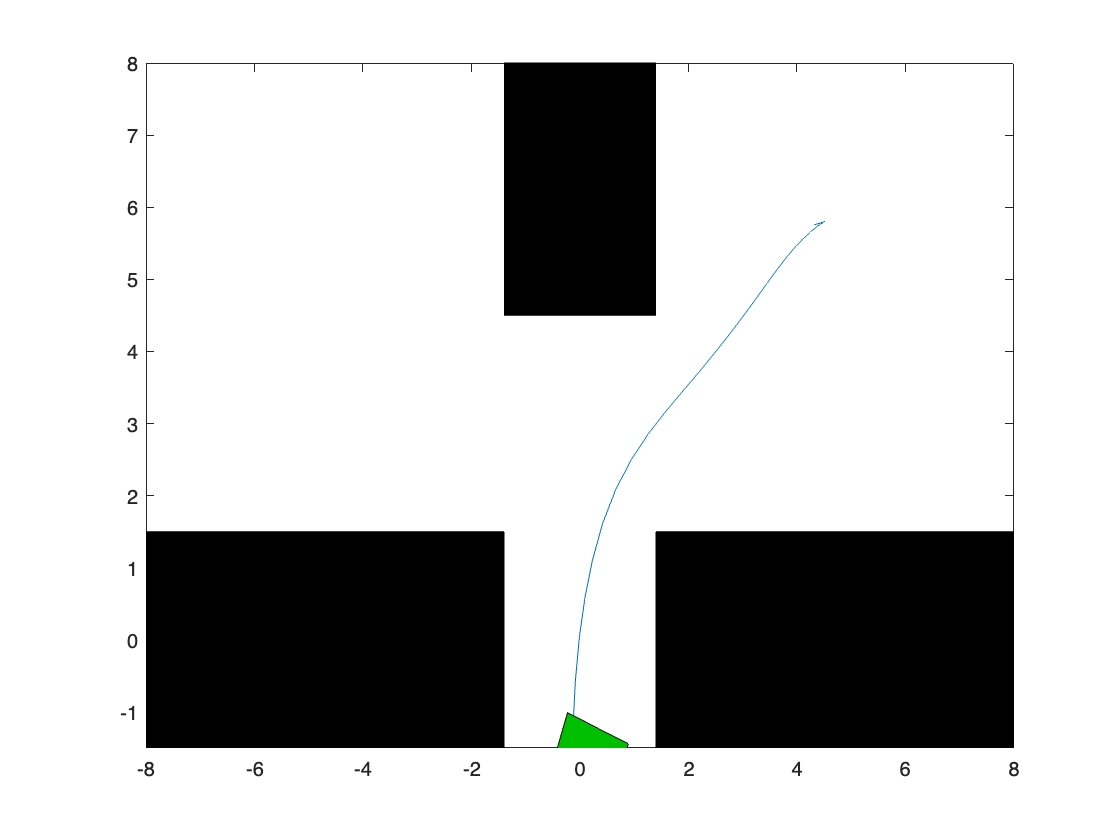


% tracing the 2D trajectory the robot took 
obs = simout.Observation.obs1.Data;
obsmat = squeeze(obs);
x = obsmat(1,:);
y = obsmat(2,:);
plot(x,y);

%learning graph 
opts = rlSimulationOptions("MaxSteps",100,"NumSimulations",10); 
simout = sim(agent,env,opts);

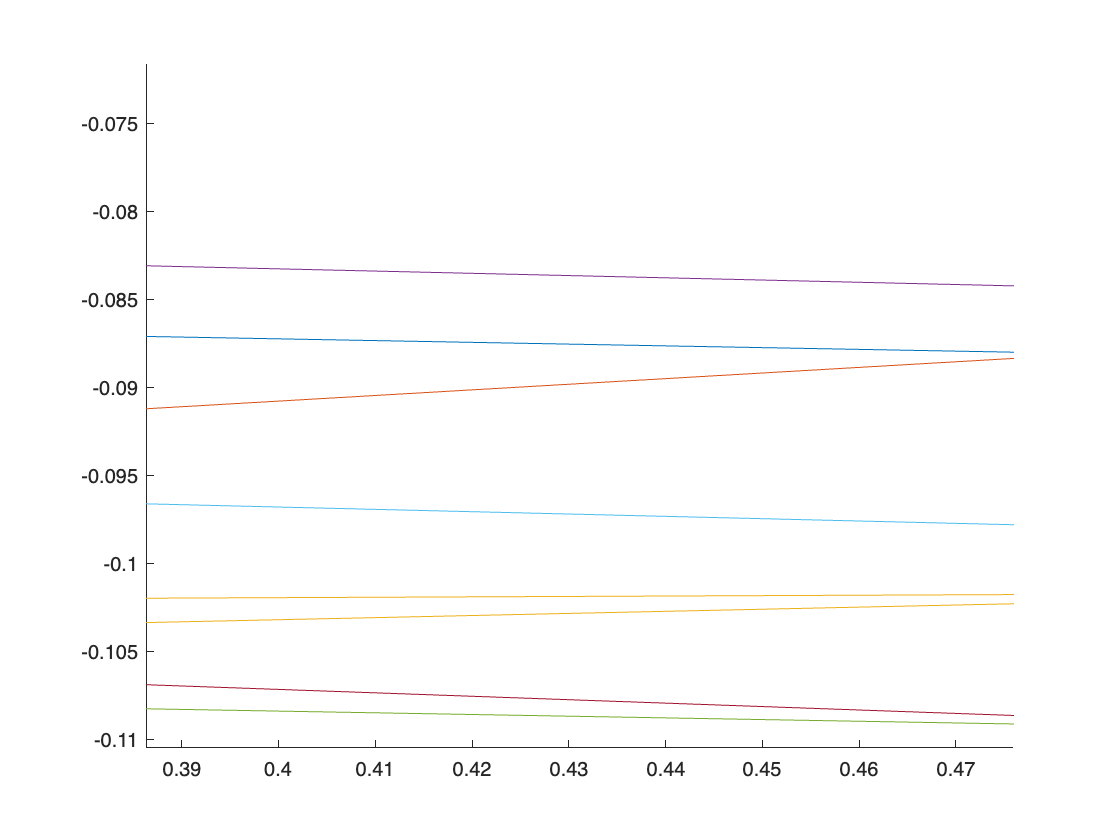

figure 
hold on 
for k = 1:10
    s = simout(k);
    t = s.Reward.Time;
    r = s.Reward.Data;
    plot(t,r)
end
hold off